M = 16;                     %Comment
k = log2(M);                %
n = 30000;                  %
numSamplePerSymbol = 1;     %

rng default;

rng('default') は、rand、randi および randn で使用される乱数発生器の設定を既定値に指定します。これにより、MATLAB を再起動したかのように、同じ乱数が生成されます。既定の設定は、seed が 0 のメルセンヌ・ツイスターです。

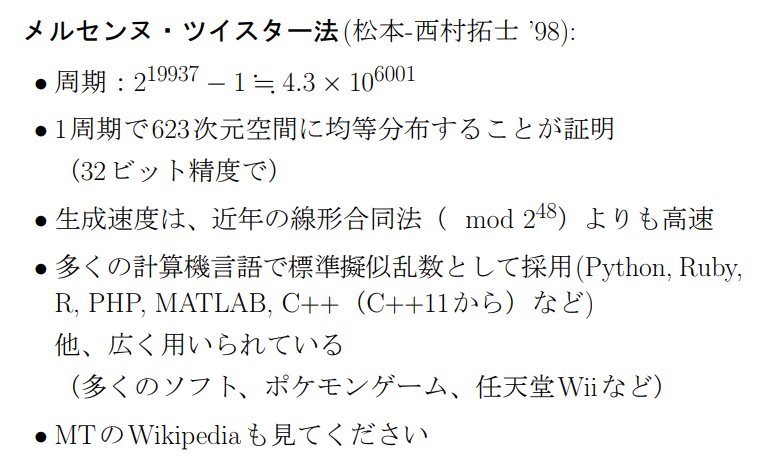

dataIn = randi([0,1],n,1); % 0 ~ 1 の間の値でランダムにn個出力。データのステップは1。

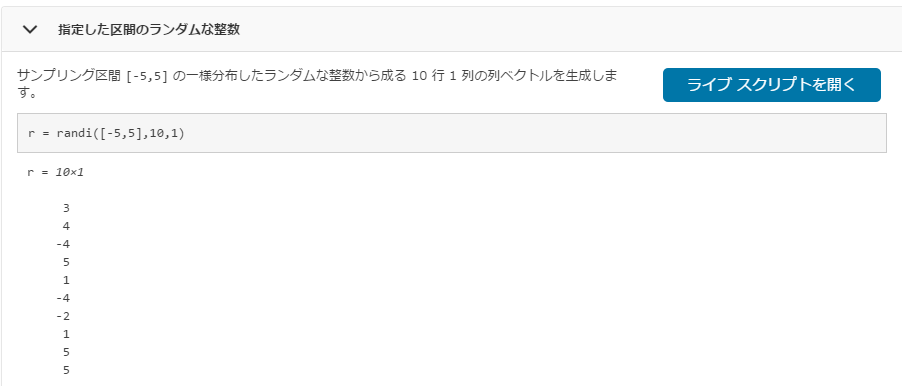

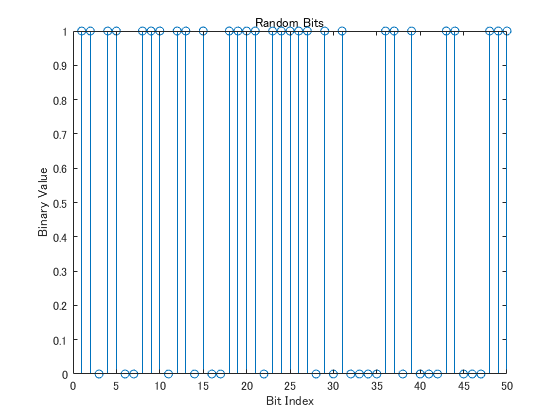

stem(dataIn(1:50)); %離散データ列のプロット
title('Random Bits');
xlabel('Bit Index');
ylabel('Binary Value');

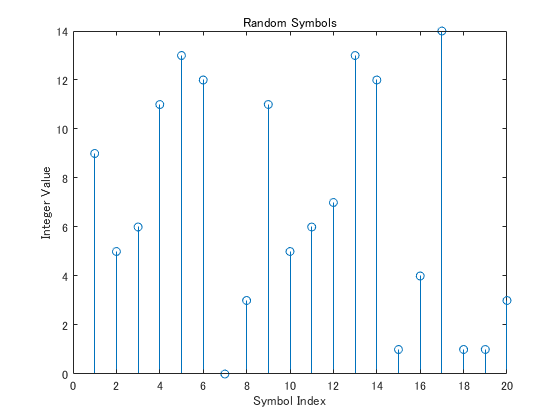

dataInMatrix = reshape(dataIn,length(dataIn)/k,k); %reshapeは次元変更関数：dataIn(30000行1列)を30000行k列に変換
dataSymbolsIn = bi2de(dataInMatrix); %2進数から10進数への変換

figure;
stem(dataSymbolsIn(1:20));
title('Random Symbols');
xlabel('Symbol Index');
ylabel('Integer Value');

dataMod = qammod(dataSymbolsIn,M,'bin');
dataModG = qammod(dataSymbolsIn,M); %シンボル順序のデフォルトはGray

EbN0 = 10;
snr = EbN0 + 10*log10(k) - 10*log10(numSamplePerSymbol)

snr = 16.0206

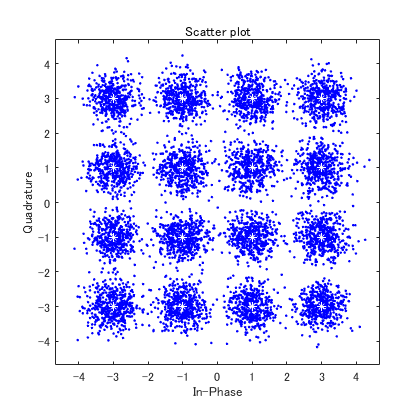


receivedSignal = awgn(dataMod,snr,'measured');
receivedSignalG = awgn(dataModG,snr,'measured');

sPlot1 = scatterplot(receivedSignal,1,0,'green.');
hold on
sPlot2 = scatterplot(dataMod,1,0,'black*',sPlot1);
sPlot1G = scatterplot(receivedSignalG,1,0,'b.');
hold on
sPlot2G = scatterplot(dataModG,1,0,'white*',sPlot1G);

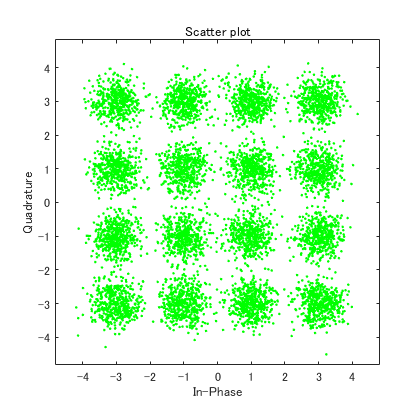

scatterplot(receivedSignal,1,0,'green.');
hold on

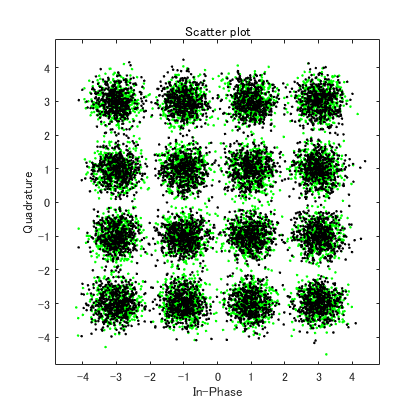

scatterplot(receivedSignalG,1,0,'black.',sPlot1);


dataSymbolsOut = qamdemod(receivedSignal,M,'bin');
dataSymbolsOutG = qamdemod(receivedSignalG,M);

dataOutMatrix = de2bi(dataSymbolsOut,k);
dataOut = dataOutMatrix(:);
dataOutMatrixG = de2bi(dataSymbolsOutG,k);
dataOutG = dataOutMatrixG(:);

[numErrors,ber] = biterr(dataIn,dataOut)

numErrors = 72

ber = 0.0024

fprintf('\nThe binary coding bit error rate = %5.2e, based on %d errors\n',ber,numErrors)


The binary coding bit error rate = 2.40e-03, based on 72 errors


[numErrorsG,berG] = biterr(dataIn,dataOutG)

numErrorsG = 40

berG = 0.0013

fprintf('\nThe binary coding bit error rate = %5.2e, based on %d errors\n',berG,numErrorsG)


The binary coding bit error rate = 1.33e-03, based on 40 errors


# **16-QAM のバイナリ シンボル マッピングのコンスタレーション**

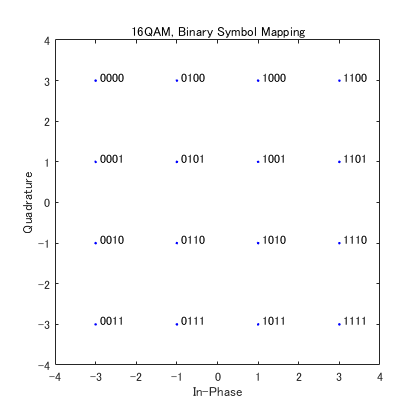

M = 16;
x1 = (0:15);
x = (0:15)';
y1 = qammod(x,M,'bin');
y2 = qammod(x,M);

scatterplot(y1);
text(real(y1)+0.1,imag(y1)+0.1,dec2bin(x));
title('16QAM, Binary Symbol Mapping');
axis([-4 4 -4 4])

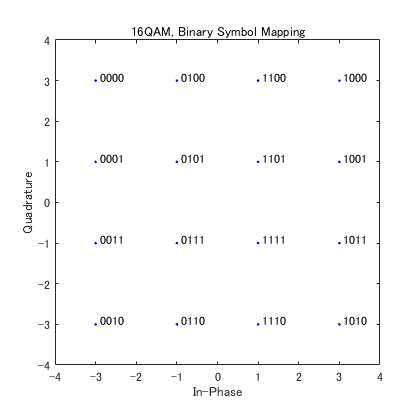

scatterplot(y2);
text(real(y2)+0.1,imag(y2)+0.1,dec2bin(x));
title('16QAM, Binary Symbol Mapping');
axis([-4 4 -4 4])

# **レイズド コサイン フィルターの作成**


M = 16;
k = log2(M);
numBits = 3e5;
numSamplePerSymbol = 4;

span = 10;
rolloff = 0.25;

rrcFilter = rcosdesign(rolloff,span,numSamplePerSymbol)

rrcFilter =    -0.0038   -0.0057   -0.0015    0.0064    0.0106    0.0050   -0.0091   -0.0213   -0.0188    0.0030    0.0327    0.0471    0.0265   -0.0275   -0.0852   -0.0994   -0.0321    0.1189    0.3109    0.4716    0.5342    0.4716    0.3109    0.1189   -0.0321   -0.0994   -0.0852   -0.0275    0.0265    0.0471    0.0327    0.0030   -0.0188   -0.0213   -0.0091    0.0050    0.0106    0.0064   -0.0015   -0.0057   -0.0038


%fvtool(rrcFilter,'Analysis','magnitude','impulse');
%fvtool(rrcFilter,'Analysis','impulse');
%fvtool(rrcFilter,'Analysis','info');
%fvtool(rrcFilter,'Analysis','step','grid','off','legend','on');

# **BER シミュレーション**

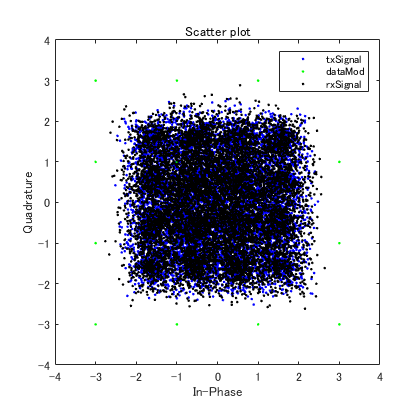

txSignal = upfirdn(dataMod,rrcFilter,numSamplePerSymbol,1);
sPlot3 = scatterplot(txSignal(1:10000),1,0,'blue.');

hold on

scatterplot(dataMod(1:1000),1,0,'green.',sPlot3);
axis([-4 4 -4 4]);

hold on

rxSignal = awgn(txSignal,snr,'measured');
scatterplot(rxSignal(1:10000),1,0,'black.',sPlot3);
legend('txSignal','dataMod','rxSignal');
hold off

# アップサンプリング

- 行列 `xin` 内の入力データに対する、整数 `p` によるアップサンプリング (ゼロの挿入)

- ベクトルまたは行列 `h` で与えられた**インパルス応答**シーケンスによる、アップサンプリングした信号データの FIR フィルター処理

- 整数 `q` によるダウンサンプリング (サンプルの間引き)

# インパルス応答

%imp = [1; 2;]
%imp = [1; zeros(49,1)]
imp = eye(50,1)

imp =      1
     0
     0
     0
     0
     0
     0
     0
     0
     0


b = 1;
a = [1 -0.9]

a =     1.0000   -0.9000


h = filter(b,a,imp)

h =     1.0000
    0.9000
    0.8100
    0.7290
    0.6561
    0.5905
    0.5314
    0.4783
    0.4305
    0.3874


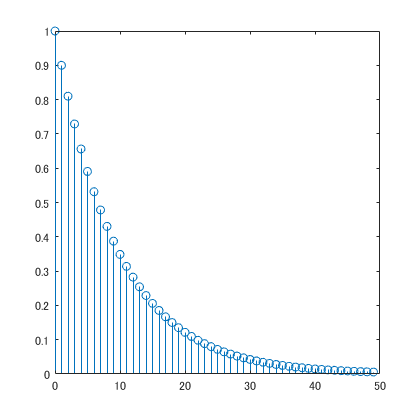

stem(0:49,h)

%fvtool(b,a,'analysis','impulse');

Fdat = 48e3;
Fcd = 44.1e3;
[L,M] = rat(Fcd/Fdat)
N = 24*L;
h = fir1(N-1,1/M,kaiser(N,7.8562))

h =    -0.0332   -0.0241   -0.0147   -0.0050    0.0051    0.0155    0.0263    0.0375    0.0490    0.0609    0.0731    0.0856    0.0986    0.1118    0.1255    0.1395    0.1538    0.1684    0.1834    0.1988    0.2145    0.2305    0.2468    0.2635    0.2805    0.2978    0.3154    0.3333    0.3516    0.3701    0.3889    0.4080    0.4273    0.4469    0.4668    0.4870    0.5073    0.5279    0.5488    0.5699    0.5911    0.6126    0.6343    0.6561    0.6781    0.7003    0.7226    0.7450    0.7676    0.7903


h = L*h;
n = 0:10240-1;
x = sin(2*pi*1e3/Fs*n);
y = upfirdn(x,h,L,M)

y =          0    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0000   -0.0001    0.0012    0.1378    0.2786    0.4114    0.5371    0.6512    0.7525    0.8383    0.9072    0.9577    0.9889    0.9999    0.9908    0.9615    0.9128    0.8455    0.7611    0.6613    0.5481    0.4238    0.2909    0.1521    0.0102   -0.1318   -0.2712   -0.4052   -0.5309   -0.6458   -0.7477   -0.8344   -0.9042   -0.9557   -0.9878   -0.9999   -0.9917   -0.9634   -0.9156   -0.8493   -0.7657


stem(n(1:49)/Fs,x(1:49))
hold on
reX = n(2:45)/(Fs*L/M)

reX = 	1.0e+-3 *

    0.0227    0.0454    0.0680    0.0907    0.1134    0.1361    0.1587    0.1814    0.2041    0.2268    0.2494    0.2721    0.2948    0.3175    0.3401    0.3628    0.3855    0.4082    0.4308    0.4535    0.4762    0.4989    0.5215    0.5442    0.5669    0.5896    0.6122    0.6349    0.6576    0.6803    0.7029    0.7256    0.7483    0.7710    0.7937    0.8163    0.8390    0.8617    0.8844    0.9070    0.9297    0.9524    0.9751    0.9977


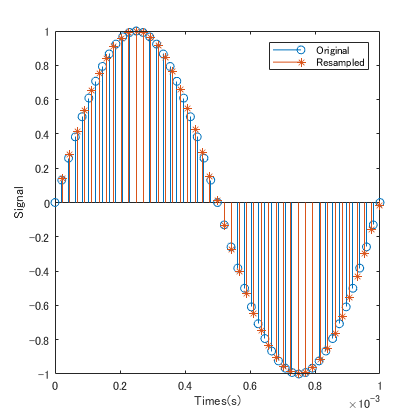

stem(n(2:45)/(Fs*L/M),y(13:56),'*')
hold off
xlabel('Times(s)')
ylabel('Signal')
legend('Original','Resampled')